clf;
%%Testskript für die Blattauslegung mit Betz/Schmitz
%%zum erstellen eines neuen Profils Rotorradius, schnelllaufzahl und
%%Blattanzahl. Danach noch den profilnamen eingeben (z. Zt. gehen nur NACA
%%4-Digit Profile. der Radius bei dem das Profil hinzugefügt werden soll, 
%%Anstellwinkel,  und Postion der Blattachse eingeben. Zum Bearbeiten muss
%%"edit" auf 1 gesetzt sein. Ansonsten werden nur vorhanden Profile
%%geplottet

%%globale Variablen des Rotors
R=50;           %%Rotorradius [m]
lamda_A=7;      %%Schnelllaufzahl   [1]
z=3;            %%Blattanzahl       [1}

%%lokale Variablen zum einfgügen der Profile
name='NACA0012';    %%Profilname gerade nur NACA 4-digit profile, z.B. "NACA0012", oder "Cir_2.1" für 2.1m kreis
%%alpha_A=6;          %%Anstellwinkel     [°]
t=0.25;             %%Position Blattachse
r=16;               %%Position des Profils auf dem Blatt

edit=1;             %%edit an oder aus

## Profile erstellen und anhängen

if edit==1
   if exist('prof')==0
       prof(1)=profile_transform(R,r,name,lamda_A,z, t);
   else
       if check_existing(prof,r) == 0
            l=length(prof);
            prof(l+1)=profile_transform(R,r,name,lamda_A,z, t);
            prof=bld_sort(prof);
       else
           disp('Profil an dieser Blattposition existiert bereits. Anderen Profilposition waehlen!')
       end
   end
end

existing = logical
   0


alpha_A = 16

deep_bld = 8.7332

profile =     6.5499    6.4950    6.3994    6.2878    6.1627    6.0281    5.8880    5.7450    5.6003    5.4548    5.3091    5.1629    5.0167    4.8704    4.7241    4.5777    4.4312    4.2848    4.1384    3.9919    3.8454    3.6991    3.5527    3.4064    3.2601    3.1139    2.9679    2.8219    2.6760    2.5302    2.3846    2.2392    2.0939    1.9488    1.8040    1.6593    1.5150    1.3709    1.2271    1.0836    0.9406    0.7979    0.6556    0.5139    0.3727    0.2321    0.0922   -0.0469   -0.1851   -0.3223
    0.0154    0.0230    0.0361    0.0513    0.0680    0.0856    0.1037    0.1217    0.1396    0.1573    0.1746    0.1916    0.2084    0.2248    0.2410    0.2568    0.2722    0.2873    0.3021    0.3165    0.3307    0.3445    0.3579    0.3709    0.3836    0.3959    0.4077    0.4192    0.4301    0.4406    0.4507    0.4602    0.4692    0.4777    0.4855    0.4928    0.4994    0.5053    0.5106    0.5150    0.5187    0.5215    0.5234    0.5243    0.5243    0.5232    0.5210    0.5176    0.513

## plot

bld_plot(prof);

l = 2

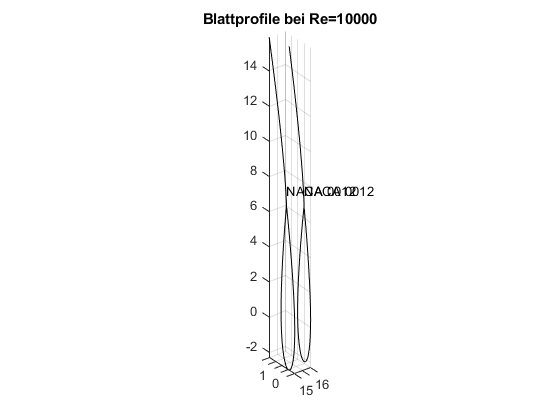

title('Blattprofile bei Re=10000')
grid on;